%clearing crap
clear all; close all; clc;

%importing required packages
addpath("C://Users/Jack/Documents/MATLAB Pacakges/alchemyst_ternplot_250124/")


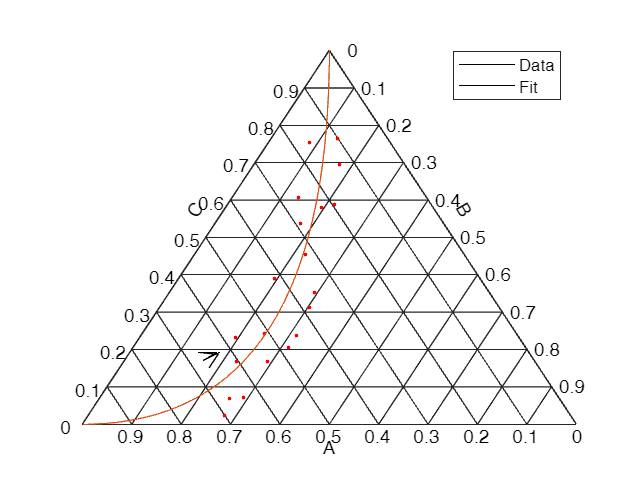

%Source: https://github.com/alchemyst/ternplot/blob/master/terndemo.m
%% Simple two-d plot

dataA = linspace(0.1, 0.7, 20);
dataB = -dataA.^2 + dataA + (rand(size(dataA)) - 0.5)/7;
dataC = 1 - dataA - dataB;

A = linspace(0, 1, 100);
B = -A.^2+A;

ternplot(dataA, dataB, dataC, 'r.', 'majors', 5);
hold on
ternplot(A, B)
ternlabel('A', 'B', 'C')
legend('Data', 'Fit')
hold off

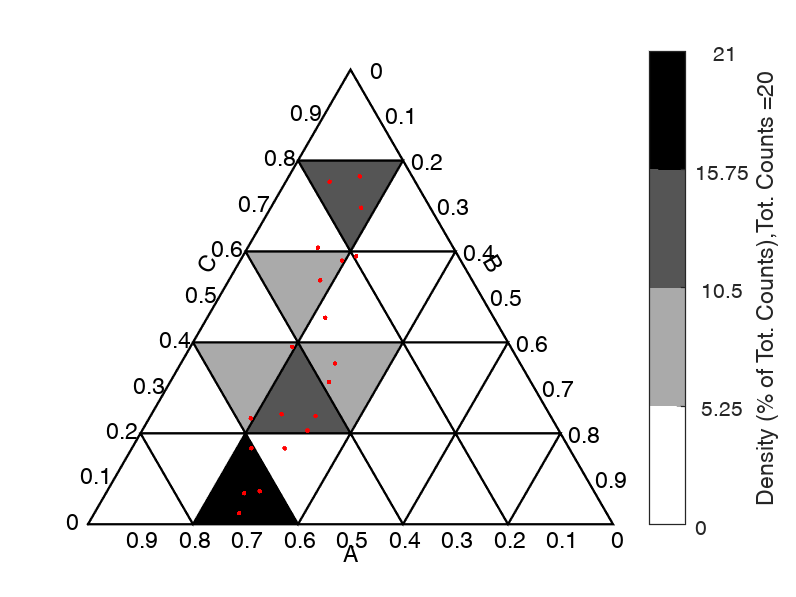


%% Simple two-d density plot
num_axes_steps = 5;
num_color_classes = 5;
ternplot_pro(dataA, dataB, dataC, num_axes_steps, num_color_classes);
ternlabel('A', 'B', 'C');
hold on
ternplot(dataA, dataB, dataC, 'r.');
hold off

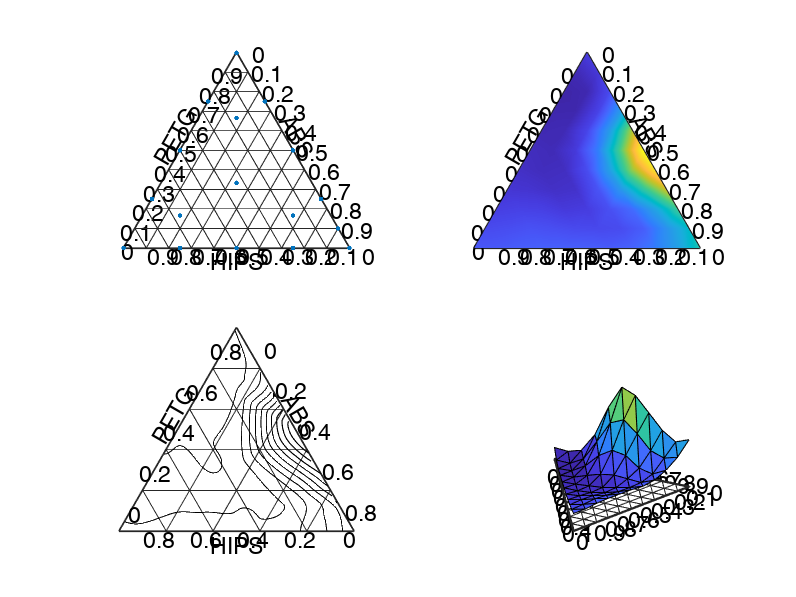


%% Three D plot for viscosity of HIPS, ABS and PETG polymer blends
experimental = [...
    1.000	0.000	0.000
    0.000	1.000	0.000
    0.000	0.000	1.000
    0.500	0.500	0.000
    0.500	0.000	0.500
    0.000	0.500	0.500
    0.333	0.333	0.333
    0.750	0.250	0.000
    0.250	0.750	0.000
    0.750	0.000	0.250
    0.250	0.000	0.750
    0.000	0.750	0.250
    0.000	0.250	0.750
    0.667	0.167	0.167
    0.167	0.667	0.167
    0.167	0.167	0.667
    0.000	0.900	0.100];
data = [...
    0.139
    0.373
    0.089
    0.151
    0.056
    0.679
    0.095
    0.153
    0.178
    0.084
    0.040
    0.463
    0.163
    0.111
    0.170
    0.072
    0.333];

A = experimental(:, 1)';
B = experimental(:, 2)';
C = 1 - (A + B);

figure
subplot(2, 2, 1)
ternplot(A, B, C, '.'); ternlabel('HIPS', 'ABS', 'PETG');
subplot(2, 2, 2)
ternpcolor(A, B, data); ternlabel('HIPS', 'ABS', 'PETG');
shading interp
subplot(2, 2, 3)
terncontour(A, B, data); ternlabel('HIPS', 'ABS', 'PETG');
subplot(2, 2, 4)
ternsurf(A, B, data);

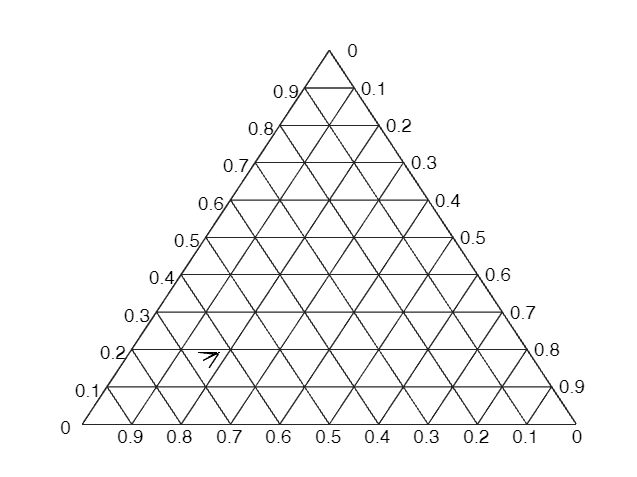

Error using plot
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow',
'black', 'white', and 'none'. Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.

Error in ternplot (line 73)
q = plot(x, y, varargin{:});

%read data
data = readtable("C://Users/Jack/Desktop/Ebele/melt_temp.csv");

x = data{:,1};
y = data{:,2};
z = data{:,3};
values = data{:,4};

